## Matrixes product order is not conmutative

% Performing rotation in X-Y-Z order
R = rotz(90)*roty(180)*rotx(90);
T = HTM(R)

T =      0     0     1     0
    -1     0     0     0
     0    -1     0     0
     0     0     0     1


% Performing rotation in Z-Y-X order
R = rotx(90)*roty(180)*rotz(90);
T = HTM(R)

T =      0     1     0     0
     0     0     1     0
     1     0     0     0
     0     0     0     1


R = rotx(90)*roty(180);
p = [10 5 0]';

T1 = HTM(R);
T2 = HTM(eye(3,3), p);

% Performing traslation followed by rotation
T = T1*T2

T =     -1     0     0   -10
     0     0     1     0
     0     1     0     5
     0     0     0     1


% Performing rotation followed by traslation
T = T2*T1

T =     -1     0     0    10
     0     0     1     5
     0     1     0     0
     0     0     0     1


## Solving for vector **r**

p = [6 -3 8]';
T = HTM(eye(3,3), p);

ruvw = [-2 7 3 1]';

% Calculating vector r coordinates from UVW to XYZ system
rxyz = T*ruvw

rxyz =      4
     4
    11
     1


% Calculating new vector r coordinates in XYZ system
rxyz_prime = T*rxyz

rxyz_prime =     10
     1
    19
     1


R = rotx(90);
p = [8 -4 12]';

% Performing rotation followed by traslation
T = HTM(eye(3,3), p)*HTM(R)

T =      1     0     0     8
     0     0    -1    -4
     0     1     0    12
     0     0     0     1



ruvw = [-3 4 -11 1]';

% Calculating vector r coordinates from UVW to XYZ system
rxyz = T*ruvw

rxyz =      5
     7
    16
     1


% Performing traslation followed by rotation
T = HTM(R)*HTM(eye(3,3), p)

T =      1     0     0     8
     0     0    -1   -12
     0     1     0    -4
     0     0     0     1


% Calculating vector r coordinates from UVW to XYZ system
rxyz = T*ruvw

rxyz =      5
    -1
     0
     1


## Homogeneous Matrixes Composition

% Performing rotx(-90) - pxyz(5 5 10) - rotz(90)
R1 = rotx(-90);
pxyz = [5 5 10]';
R2 = rotz(90);

% Performing operations using XYZ fixed system as reference
T = HTM(R2) * HTM(eye(3), pxyz) * HTM(R1)

T =      0     0    -1    -5
     1     0     0     5
     0    -1     0    10
     0     0     0     1


% Performing pxyz(-3 10 10) - rotu(-90) - rotv(90)
pxyz = [-3 10 10]';
R1 = rotx(-90);
R2 = rotz(90);

% Performing operations using UVW system as reference
T = HTM(eye(3), pxyz) * HTM(R1) * HTM(R2)

T =      0    -1     0    -3
     0     0     1    10
    -1     0     0    10
     0     0     0     1


% 1. If XYZ and UVW systems are identical, the homogeneous
% transformation matrix will be a 4x4 intity matrix
%
% 2. If UVW is obtained by rotation/translation using XYZ fixed system,
% the homogeneous matrix that represents every transformation will have
% to premultiply following the inverse order
%
% 3. If UVW is obtained by rotation/translation using a movile system,
% the homogeneous matrix that represents every transformation will have
% to postmultiply following the same order

R = rotz(90)*roty(180)*rotx(90);
T = HTM(R)

T =      0     0     1     0
    -1     0     0     0
     0    -1     0     0
     0     0     0     1


% Rotating in X-Y-Z order using XYZ fixed system as reference
% or
% Rotating in W-V-U order using UVW system as reference

## Transformation Graphs

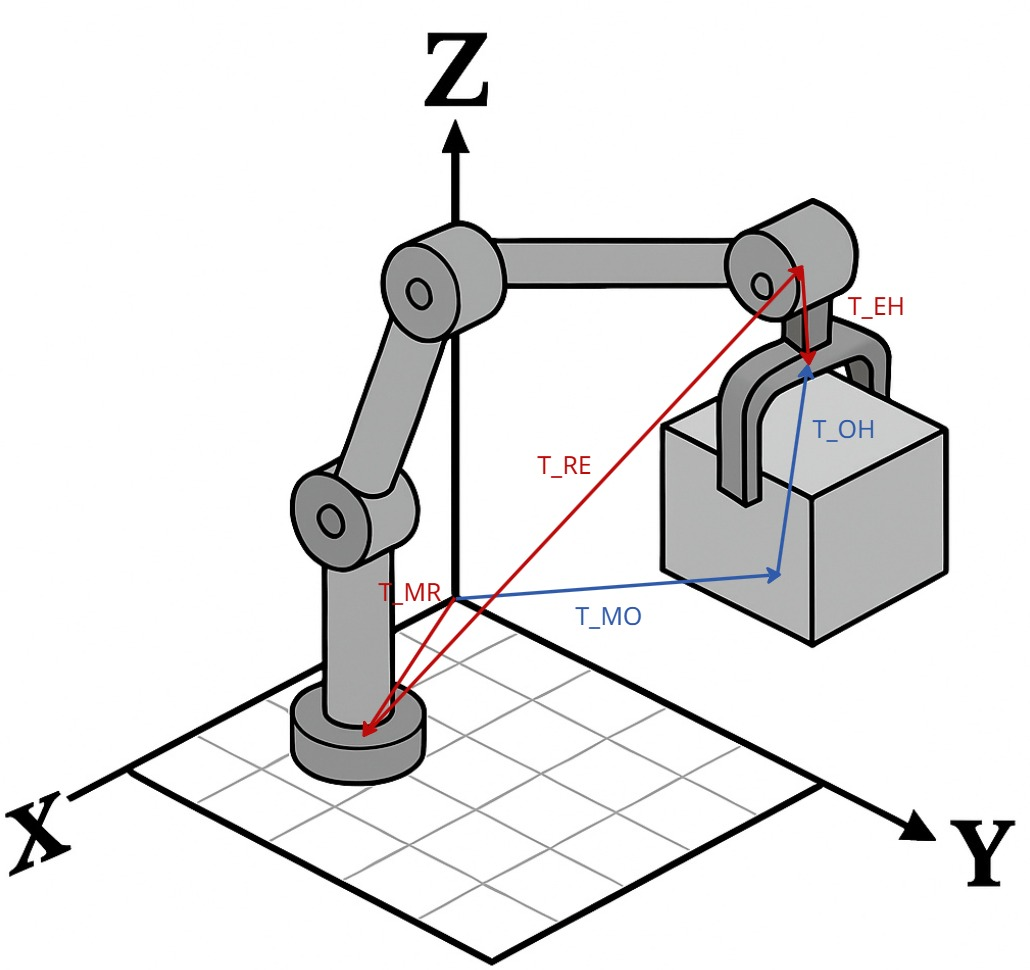

% Not applying rotation to keep it simple

% Origin - Manipulator's Base
T_MR = HTM(eye(3), ([3 1 0]'));
% Manipulator's Base - Final Actuator's Base
T_RE = HTM(eye(3), ([-1 5 10]'));
% Final Actuator's Base - Final Actuator's Tip
T_EH = HTM(eye(3), ([0 0 -1]'));

% Origin - Object
T_MO = HTM(eye(3), ([2 6 8]'));
% Object - Final Actuator's Tip
T_OH = HTM(eye(3), ([0 0 1]'));

% The Final Actuator's Tip can be refered with respect to the XYZ fixed system in two different ways.
T1 = T_MR * T_RE * T_EH

T1 =      1     0     0     2
     0     1     0     6
     0     0     1     9
     0     0     0     1


T2 = T_MO * T_OH

T2 =      1     0     0     2
     0     1     0     6
     0     0     1     9
     0     0     0     1


all(all( T1 == T2 ))

ans = logical
   1


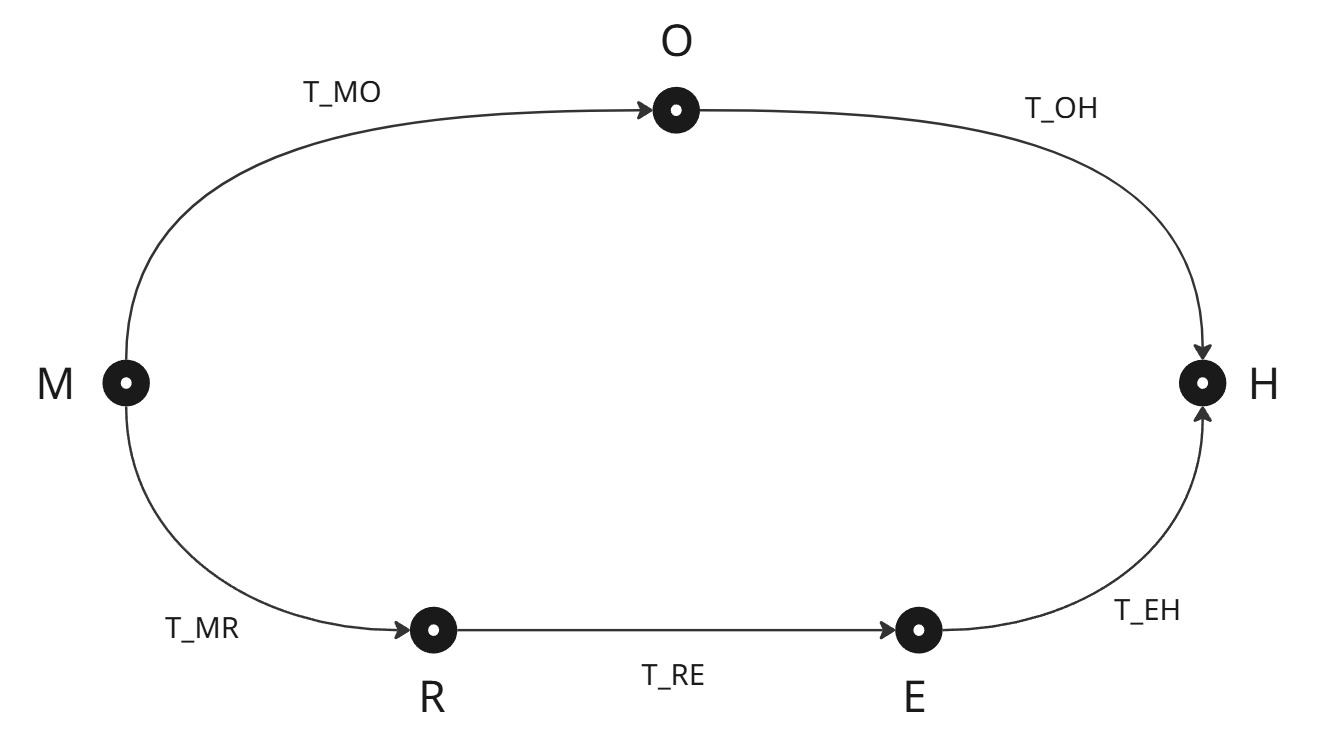

% The relationship between the object and the final actuator's tip
T1 = T_MR * T_RE * T_EH * T_MO^(-1)

T1 =      1     0     0     0
     0     1     0     0
     0     0     1     1
     0     0     0     1


T2 = T_OH

T2 =      1     0     0     0
     0     1     0     0
     0     0     1     1
     0     0     0     1


all(all( T1 == T2 ))

ans = logical
   1


% The relationship between the manipulator's base and the object
T1 = T_RE * T_EH * T_OH^(-1)

T1 =      1     0     0    -1
     0     1     0     5
     0     0     1     8
     0     0     0     1


T2 = T_MO * T_MR^(-1)

T2 =      1     0     0    -1
     0     1     0     5
     0     0     1     8
     0     0     0     1


all(all( T1 == T2 ))

ans = logical
   1


## Quaternion Operations

Q1 = Quaternion([1 1 1 1]);
Q2 = Quaternion([2 3 4 5]);

% Addition
Q1 + Q2

ans =   Quaternion with properties:

    Vector: [3 4 5 6]


% Subtraction
Q2 - Q1

ans =   Quaternion with properties:

    Vector: [1 2 3 4]


% Multiplication
Q1 * Q2

ans =   Quaternion with properties:

    Vector: [-10 6 4 8]


Q2 * Q1

ans =   Quaternion with properties:

    Vector: [-10 4 8 6]


% Conjugation
Q1.conjugate()

ans =   Quaternion with properties:

    Vector: [1 -1 -1 -1]


Q2.conjugate()

ans =   Quaternion with properties:

    Vector: [2 -3 -4 -5]


% Norma
Q1.norma()

ans = 2

Q2.norma()

ans = 7.3485

% Obtaining quaternion that represents a 90 degree rotation over u axis where u = [3 -2 1]

u = [3 -2 1];
theta = pi/2;

% Unitarian vector k
k = 1/norm(u) * [3 -2 1];

% Solving for the cuaternion Q
Q = Quaternion([cos(theta/2) sin(theta/2)*ones(1,3).*k])

Q =   Quaternion with properties:

    Vector: [0.7071 0.5669 -0.3780 0.1890]


% Obtaining vector r' by applying same rotation in the previous example where r = [5 2 -6]
r = [5 2 -6];

% Solving for r'
r_prime = Q * Quaternion([0 r]) * Q.conjugate()

r_prime =   Quaternion with properties:

    Vector: [1.1102e-16 3.7440 5.4327 4.6333]


% Solving vector r coordinates using XYZ system when performing traslation p followed by rotation Q
ruvw = [3 -1 4];
p = [1 1 1];
rxyz = Q * Quaternion([0 ruvw]) * Q.conjugate() + Quaternion([0 p])

rxyz =   Quaternion with properties:

    Vector: [0 2.3435 -3.5482 2.8732]


% Solving vector r coordinates using XYZ system when performing rotation Q followed by traslation p
rxyz = Q * Quaternion([0 ruvw+p]) * Q.conjugate()

rxyz =   Quaternion with properties:

    Vector: [-4.4409e-16 0.9702 -5.3684 3.3524]


% Solving vector r coordinates using UVW system when performing traslation p followed by rotation Q
ruvw = [1 5 -2];
p = [3 0 1];
rxyz = Q * Quaternion([0 ruvw+p]) * Q.conjugate()

rxyz =   Quaternion with properties:

    Vector: [-2.4980e-16 -0.5875 1.7280 6.2184]


% Solving vector r coordinates using UVW system when performing rotation Q followed by traslation p
rxyz = Q * Quaternion([0 ruvw]) * Q.conjugate() + Quaternion([0 p])

rxyz =   Quaternion with properties:

    Vector: [4.4409e-16 0.8042 3.1565 4.9006]


## RELATIONSHIP BETWEEN QUATERNIONS AND HTM

% Direct relationship
% From a previous example
u = [3 -2 1];
theta = pi/2;

% Unitarian vector k
k = 1/norm(u) * [3 -2 1];

% Solving for the cuaternion Q
Q = Quaternion([cos(theta/2) sin(theta/2)*ones(1,3).*k])

Q =   Quaternion with properties:

    Vector: [0.7071 0.5669 -0.3780 0.1890]


q0 = Q.Vector(1);
q1 = Q.Vector(2);
q2 = Q.Vector(3);
q3 = Q.Vector(4);

nx = 2*(q0^2 + q1^2) - 1;
ox = 2*(q1*q2 - q0*q3);
ax = 2*(q1*q3 + q0*q2);

ny = 2*(q1*q2 + q0*q3);
oy = 2*(q0^2 + q2^2) - 1;
ay = 2*(q2*q3 - q0*q1);

nz = 2*(q1*q3 - q0*q2);
oz = 2*(q2*q3 + q0*q1);
az = 2*(q0^2 + q3^2) - 1;

R = [nx ox ax; ny oy ay; nz oz az];
T = HTM(R)

T =     0.6429   -0.6958   -0.3202         0
   -0.1613    0.2857   -0.9446         0
    0.7488    0.6589    0.0714         0
         0         0         0    1.0000


% Inverse relationship
% From the same example
q0 = 1/2 * sqrt(T(1,1) + T(2,2) + T(3,3) + 1);
q1 = 1/2 * sqrt(T(1,1) - T(2,2) - T(3,3) + 1) * sign(T(3,2) - T(2,3));
q2 = 1/2 * sqrt(-T(1,1) + T(2,2) - T(3,3) + 1)* sign(T(1,3) - T(3,1));
q3 = 1/2 * sqrt(-T(1,1) - T(2,2) + T(3,3) + 1)* sign(T(2,1) - T(1,2));

Q = Quaternion([q0 q1 q2 q3])

Q =   Quaternion with properties:

    Vector: [0.7071 0.5669 -0.3780 0.1890]
